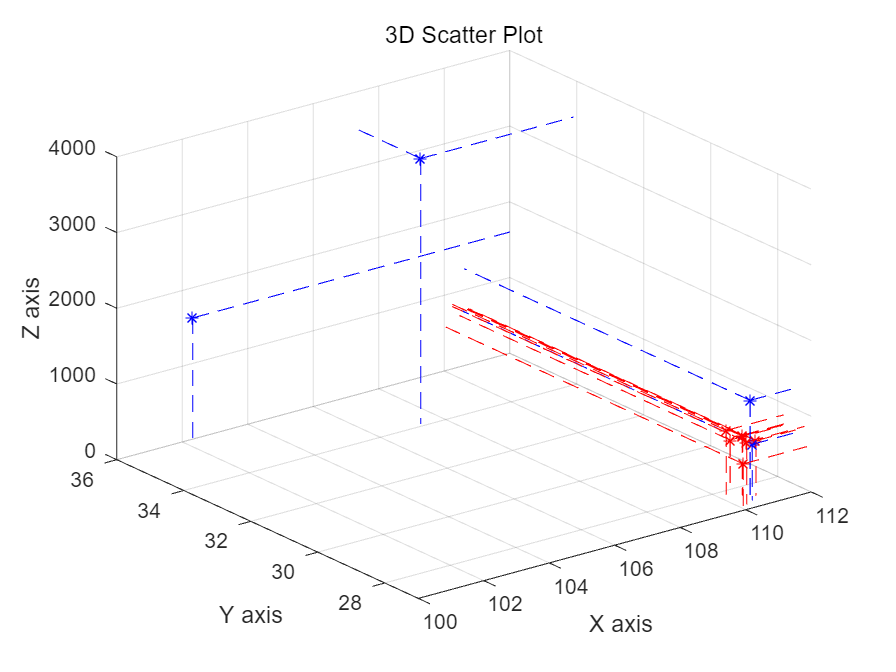

monitors = table2array(readtable("que1_data.xlsx", 'Sheet', 'Sheet1'));
point = [
    110.506    27.300    742.759;
    102.308    35.986    1605.241;
    110.608    27.462    1279.064;
    107.333    34.095    3507.197;
    ];

clf;
plot3(monitors(:,1), monitors(:,2), monitors(:,3), '*r', point(:,1), point(:,2), point(:,3), '*b'); % 'o' 表示圆形标记


% 设置图形属性
xlabel('X axis');
ylabel('Y axis');
zlabel('Z axis');
title('3D Scatter Plot');
grid on;
hold on

for i = 1:7
    plot3([monitors(i,1), monitors(i,1)], [monitors(i,2), monitors(i,2)], [monitors(i,3), 0], 'r--'); % Z 轴方向
    plot3([monitors(i,1), monitors(i,1)], [monitors(i,2), 36], [monitors(i,3), monitors(i,3)], 'r--'); % Y 轴方向
    plot3([monitors(i,1), 112], [monitors(i,2), monitors(i,2)], [monitors(i,3), monitors(i,3)], 'r--'); % X 轴方向
end

for j=1:4
    plot3([point(j,1), point(j,1)], [point(j,2), point(j,2)], [point(j,3), 0], 'b--');
    plot3([point(j,1), point(j,1)], [point(j,2), 36], [point(j,3), point(j,3)], 'b--');
    plot3([point(j,1), 112], [point(j,2), point(j,2)], [point(j,3), point(j,3)], 'b--');
end

xlim([100, 112]);
ylim([27, 36]);

view(3); % 设置视角